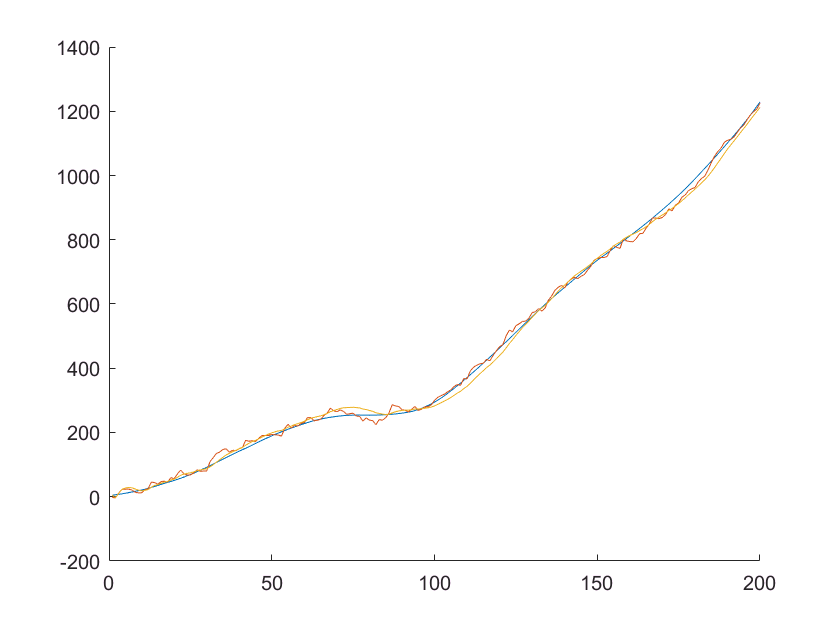

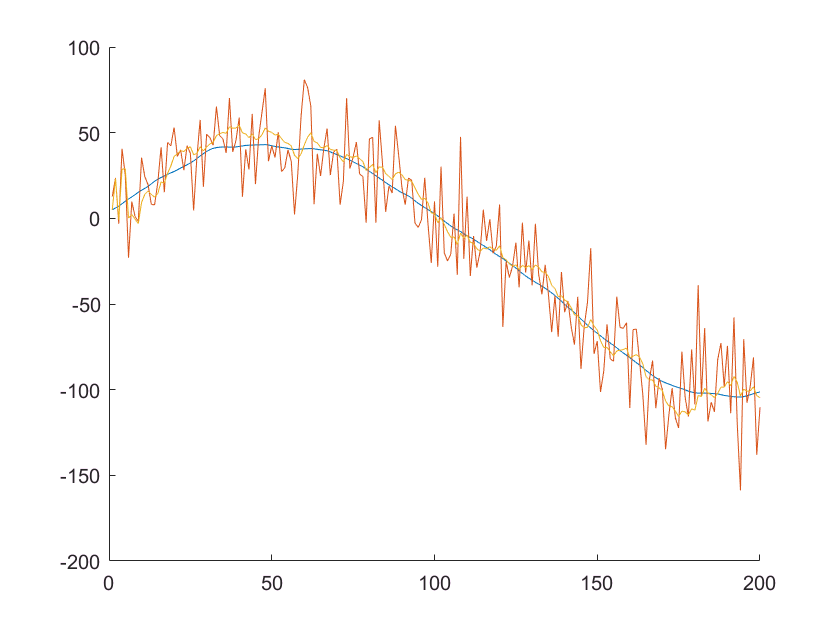

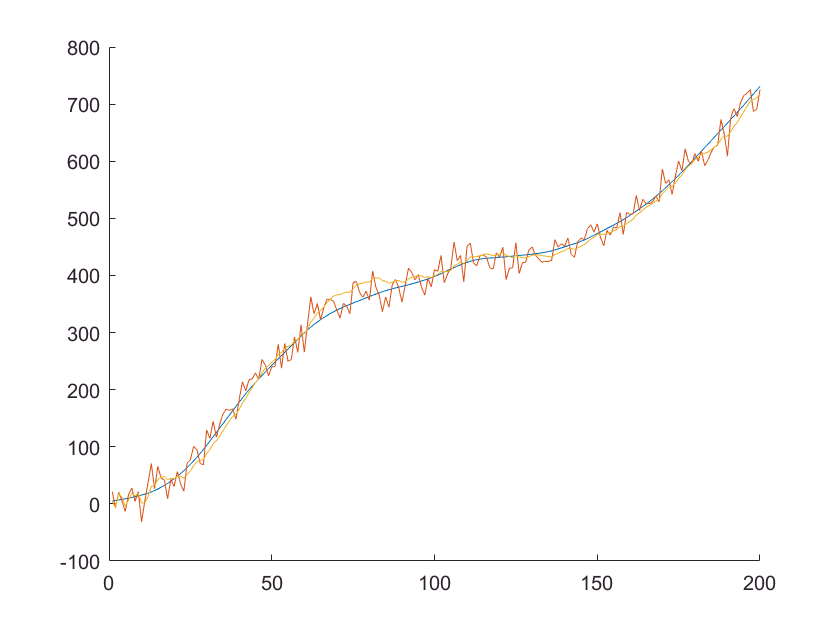

clc; clear; close all;
addpath('functions/');

n=200;
sigmaA = 0.2;
sigmaN = 20;
sigmaXi = 1;

x1=5;
v1=1;
t=1;

G = [(t^2)/2; t];
F = [1, t; 0, 1];
H = [1, 0];

ErrSum=zeros(1,n);
M=100;

Lambda = [ 0.1,  0.1; 
           1000, 1000; 
           0.1,  1000 ];

for i=1:length(Lambda)
    A = gaussMarkov( n, sigmaA, sigmaXi, Lambda(i,1), t );
    Noise = gaussMarkov( n, sigmaN, sigmaXi, Lambda(i,2), t );
    [ X, Z ] = calcTrajectory( A, Noise, x1, v1, t);
    
    for j=1:M
        [ Xk, SigmaX ] = calcKalman(Z, sigmaA, sigmaN, x1, v1, F, G, H, 0);
        ErrCur = ( X(1,:) - Xk(1,:) ).^2;
        ErrSum = ErrSum + ErrCur;
    end
    FinalError = ( ErrSum(3:end)./(M-1) ).^0.5;

    figure;
    hold on
    plot(X);
    plot(Z);
    plot(Xk(1,:));

end